close all; clear all;

# Example: Temperature sensor in a room.

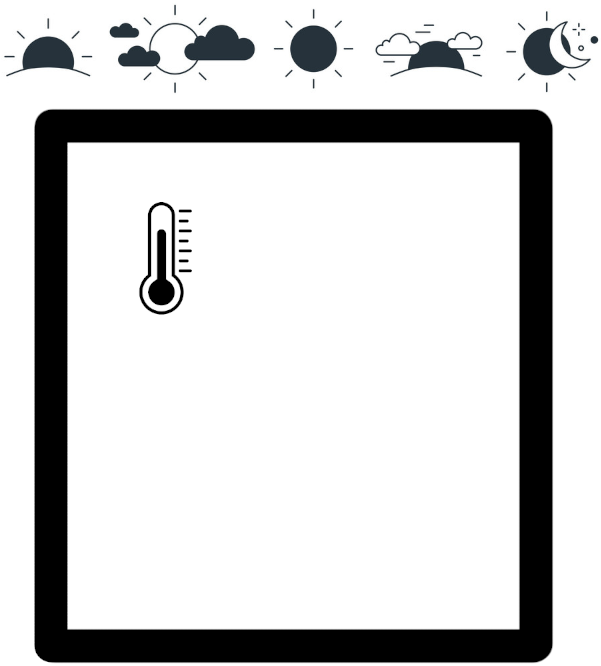

We want to use a Kalman filter to improve the measurement given by a thermometer placed in a room. The termometer is asumed to have precision of $\pm 4 ~\text{C}$. From historical meassurements it is known that the temperature is always within the range $\left[-5,+50\right]~\text{C}$ and has a maximum rate change of $\frac{20~\text{C}}{1~\text{h}}$. To test the filter check its performance along a day in which the real temperature is assumed to be $T^{actual}=\frac{38+18}{2}-\frac{38-18}{2}\sin(\frac{t}{24~60~60}~2\pi+\frac{\pi}{2})$. The sampling frequency of the filter is $\Delta t=1~\text{s}$.You will have to define process and sensor models, noise of these models, and initial conditions for the state and its covariance.

# Solution:

We define the state to be just the temperature


$$x \equiv Temp$$


The discrete model asumes that the temperature is constant with an error with a standar deviation of the change of temperature in one sampling period. So the stochastic equation has the form

$x_{k+1}=x_{k}+w_{k}$, where $x_{k+1}$ and $x_{k}$ are stochastic variables and $w_k$ is a Wiener process.

The general linear model equation being $x_{k+1}=a~x_k+b~u_k+w_k$, we have $a=1$and $b=0$.

a=1; b=zeros(1,0);

The sensor measures the state directly, therefore the sentor stochastic equation has the form

$z_{k+1}=x_{k+1}+v_{k+1}$, where $z_{k+1}$ and $x_{k+1}$ are stochastic variables and $v_{k+1}$ is a Wiener process.

The general linear sensor equation being $z_{k+1}=c~x_{k+1}+d~u_{k+1}+v_{k+1}$, we have $c=1$ and $d=0$.

c=1; d=zeros(1,0);

## Parameter and initial state definition

global t t_0 t_end Delta_t
global sigma_u_actual sigma_z_actual seed
seed=12347; rng(seed); rng_status=rng;
global z_actual_func u_actual_func
z_actual_func = @(t) actual_Temp_func(t);
u_actual_func = @(t) my_u_actual_func(t);

Set initial time $t_0$, sampling frequency $\Delta t$ and final simulation time $t_{end}$

k=0;
t_0=0;         		     %s
t=t_0;                   %s
Delta_t=1;               %s
t_end=24*60*60;          %s (one day = 24h * 60*min/h * 60s/min)

Initial state and variance $\mu_{x_0}$, $\sigma_{x_0}^2$, estimated from limits in historical meassurements

mu_x=(50+(-5))/2; n_x=size(mu_x,1); %C
sigma_x=50-mu_x;         %K
Sigma2_x=sigma_x^2;      %K^2

Model equation error variance $\sigma^2_{u_{k}}$ and $\sigma^2_{w_k}$

% Set Sigma2_u
u=u_actual_func(t);
n_u=size(u,1);

sigma_u=zeros(size(u));
Sigma2_u=diag(sigma_u)^2;
sigma_u_actual=zeros(size(u));
Sigma2_u_actual=diag(sigma_u_actual)^2;

% Set  Sigma2_w
sigma_w=[20/3600*Delta_t]; %C
Sigma2_w=diag(sigma_w)^2;  %K^2

Sensor equation error variance $\sigma^2_{z_{k+1}}$, $\sigma^2_{u_{k+1}}$ and $\sigma^2_{v_{k+1}}$

% Set Sigma2_z, Sigma2_u, Sigma2_v
sigma_z=4;                 %K Value given by spec. sheet (not exact in general)
Sigma2_z=diag(sigma_z)^2;  %K^2
sigma_z_actual=4;          %K Actual value (ideally used to setup the filter correctly)
Sigma2_z_actual=diag(sigma_z_actual)^2;      %K^2
sigma_v=0;                 %K
Sigma2_v=diag(sigma_v)^2;  %K^2

Begin filtering

fid=fopen('sol.dat','w');

Read

rng(rng_status);
z=get_z();
u=get_u();

Write

fprintf(fid,'%.20e %.20e %.20e %.20e %.20e\n',t,mu_x,Sigma2_x,z,z_actual_func(t));

Filter iteration begin

% Iteration
for k=1:t_end/Delta_t

Model Equation State *Prediction* (estimation of state in k+1 form state and input in k)

$x_{k+1}=a~x_k+b~u_k+w_k$, model stochastic equation

$\hat{\mu}_{x_1}=a \hat{\mu}_{x_{k}}+b \hat{\mu}_{u_{k}}=\hat{\mu}_{x_{k+1}^{pred}}$, *Prediction estimation*, expected value of model stochastic equation

$I_{x_1}=1/\sigma_{x_1}^2=1/(a^2\sigma_{x_k}^2+b^2\sigma_{u_k}^2+\sigma_{w_k}^2)=1/{\hat{\sigma}^2_x}^{pred}=I_{x_{k+1}}^{pred}$, Information of *Prediction estimation, inverse of variance of Prediction estimation.*

Note that $b^2\sigma_{u_k}^2+\sigma_{w_k}^2$ is what in standard Kalman filtering literature is called "model covariance matrix" $Q$ (a escalar or $1\times1$ matrix in this example)

% Process model (Prediction)
mu_x_pred=a*mu_x; % Should be mu_x_pred=a*mu_x+b*u, but u is empty
Sigma2_x_pred=Sigma2_x+Sigma2_w; % Should be Sigma2_x_pred=Sigma2_x+b^2*Sigma2_u+Sigma2_w, but u is empty
I_x_pred=1/Sigma2_x_pred;

Read

% Read (take meassurement)
t=k*Delta_t;
z=get_z();
u=get_u();

Sensor Equation State *Observation* (estimation of state in k+1 from sensor and input in k+1)

$z_{k+1}=c~x_{k+1}+d~u_{k+1}+v_{k+1} \Rightarrow  x_{k+1}=\frac{1}{c}(z_{k+1}-(d~u_{k+1}+v_{k+1}))$, sensor stochastic equation ordered to render state

$\hat{\mu}_{x_2}=\frac{1}{c} (\hat{\mu}_{z_{k+1}}+b \hat{\mu}_{u_{k+1}})=\hat{\mu}_{x_{k+1}^{obs}}$, Observation* estimation*, expected value of model stochastic equation

$I_{x2}=1/\sigma_{x_2}^2=1/(\frac{\sigma_{z_{k+1}}^2}{c^2}+\frac{d^2~\sigma_{u_{k+1}}^2}{c^2}+\frac{\sigma_{v_{k+1}}^2}{c^2})=\frac{c^2}{   {\sigma_{z_{k+1}}^2}+{d^2~\sigma_{u_{k+1}}^2}+\sigma_{v_{k+1}}^2   }=I_{x_{k+1}}^{obs}$, Information of *Observation estimation, inverse of variance of Observation estimation.*

Note that ${\sigma_{z_{k+1}}^2}+{d^2~\sigma_{u_{k+1}}^2}+\sigma_{v_{k+1}}^2}$ is what in standard Kalman filtering literature is called "sensor covariance matrix" $R$ (a escalar or $1\times1$ matrix in this example)

% Sensor model (Observation)
mu_x_obs=(z)/c; % Should be mu_x_obs=(z_noisy+d*u)/c, but u is empty
Sigma2_x_obs=(Sigma2_z+Sigma2_v)/c^2; % Should be Sigma2_x_obs=(Sigma2_z+d^2*Sigma2_u+Sigma2_v)/c^2, but u is empty
I_x_obs=1/Sigma2_x_obs;

Correction


$$\hat{\mu}_{x_{k+1}}=\frac{{I_{x_{k+1}}^{pred}}{\hat{\mu}_{x_{k+1}^{pred}}}+{I_{x_{k+1}}^{obs}}{\hat{\mu}_{x_{k+1}^{obs}}}}{{I_{x_{k+1}}}}$$



$$I_{x_{k+1}}=I_{x_{k+1}}^{pred}+I_{x_{k+1}}^{obs} \Rightarrow \sigma_{\hat{\mu}_{x_{k+1}}}^2=\frac{1}{I_{x_{k+1}}}$$


% Correction
I_total=I_x_pred+I_x_obs;
mu_x=(mu_x_pred*I_x_pred+mu_x_obs*I_x_obs)/I_total;
Sigma2_x=1/I_total;

Write

% Write
fprintf(fid,'%.20e %.20e %.20e %.20e %.20e\n',t,mu_x,Sigma2_x,z,z_actual_func(t));

Filter iteration end

end

End filtering

% End filtering
fclose(fid);

## Plotting

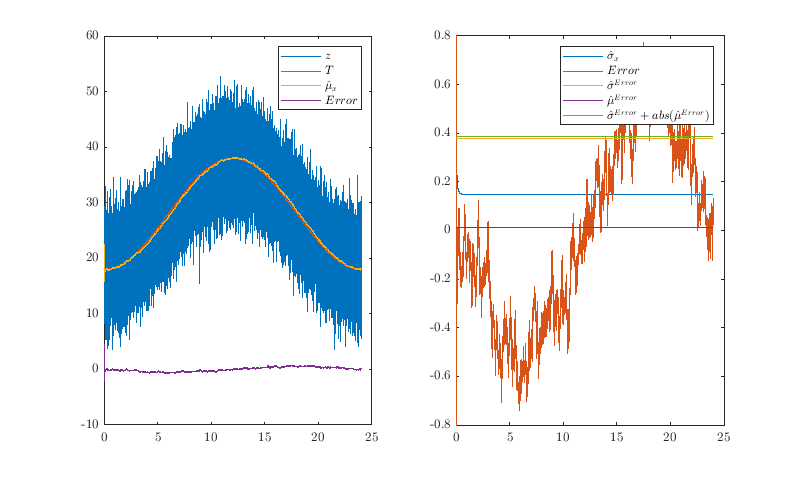

load -ascii sol.dat
t=sol(:,1)/(60*60);
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
figure('units','normalized','outerposition',[0 0 0.5 0.5]);
h(1)=subplot(1,2,1);
plot(t,sol(:,4),t,sol(:,5),t,sol(:,2),t,sol(:,2)-sol(:,5))
I=legend('$z$','$T$','$\hat{\mu}_x$', '$Error$');
set(I,'interpreter','latex');
h(2)=subplot(1,2,2);
n_window=100;
Error=sol(:,2)-sol(:,5);
plot(t,sol(:,3).^0.5,t,Error,t,ones(size(t))*std(Error),t,ones(size(t))*mean(Error),t,ones(size(t))*(std(Error)+abs(mean(Error))))
ylim([-0.8,0.8])
I=legend('$\hat{\sigma}_x$', '$Error$', ['$\hat{\sigma}^{Error}$'],['$\hat{\mu}^{Error}$'],'$\hat{\sigma}^{Error} + {abs}(\hat{\mu}^{Error})$');
set(I,'interpreter','latex');

saveas(gcf,'Temperature_sensor_in_a_room.png')

saveas(gcf,'Temperature_sensor_in_a_room.fig')

## Robustness

As $Error$ is a stochastic variable, to have a idea of the real sigma of the prediction we plot $\hat{\sigma}_{day}^{Error}$, and $\hat{\mu}_{day}^{Error}$. If the mean is not zero I would compare $\hat{\sigma}_x$ with  $\hat{\sigma}_{day}^{Error} + \text{abs}(\hat{\mu}_{day}^{Error})$.

So the filter would be adjusted in a robust way if $\hat{\sigma}_x>\hat{\sigma}_{day}^{Error} + \text{abs}(\hat{\mu}_{day}^{Error})$. That is not the case, although both errors are in the same order of magnitude, tha could be considered fine. In the Kalman filter construction hypothesis the less well justified is the one that adjust the error of the model equation, so we coul play with increasing that error until $\hat{\sigma}_x>\hat{\sigma}_{day}^{Error} + \text{abs}(\hat{\mu}_{day}^{Error})$ is satisfied.

## Functions to define sensor and input meassurement

The following function simulates the "actual" value of the variable meassured by the sensor

function z_actual=actual_Temp_func(t)
z_actual=(38+18)/2-(38-18)/2*sin(t/(24*60*60)*2*pi+pi/2);
end

The following function simulates meassurement adding noise to the "actual" value of the variable meassured by the sensor

function z_meas=get_z()
global t sigma_z_actual
global z_actual_func
z_actual=z_actual_func(t);
z_meas=z_actual+randn*sigma_z_actual;
end

The following function simulates the "actual" input to the system

function u_actual=my_u_actual_func(t)
u_actual=zeros(0,1);
end

The following function simulates input meassurement adding noise to the "actual" input to the system

function u_meas=get_u()
global t sigma_u_actual
global u_actual_func
u_actual=u_actual_func(t);
u_meas=u_actual+sigma_u_actual.*randn(size(u_actual));
end
